# Exploring Imbalanced Data and Cost Functions

Neurotechnology, Brains and Machines

Lily Jiang

Sep 24, 2023

So far, we’ve been mostly looking at “balanced” data, meaning that there are an equal number of examples in each category (e.g., 81 faces and 81 houses). Here we will explore what happens when the training data are “imbalanced”, meaning that the training labels are skewed toward one category than the other.

The purposes of this assignment are to:

- explore a code-based example of machine learning in Matlab

- see the effects of imbalanced data on machine learning

- experiment with the use of a cost matrix to counteract the effects of imbalanced data

### Exercise: Read this code and add comments to help you understand what is happening. 

## Load the data and set up analysis

load("imbalanced_fMRIvoxels.mat");

There are 5 regions: 

- r1vals (region 1), 

- r2vals (region 2)

- r3vals  (region 3)

- r4vals  (region 4)

- rfirst200vals (these are the ones not in the brain, just the first 200 voxels in the original data).

Each follows the naming format as follows, with r1vals (region 1) as an example:

- r1vals = balanced training data from region 1. Dimensions should be 162 x number of voxels

- train_labels = balanced train labels  (same regardless of region). Dimension should be 162 x 1

- r1vals_skew = imbalanced training data from region 1. Dimensions should be 100 x number of voxels. (Some trials were removed to skew our data toward faces).

- train_labels_skew = imbalanced train labels  (same regardless of region).  Dimension should be 100 x 1

- r1vals_test =  balanced test data from region 1. Dimensions should be 54 x number of voxels

- test_labels = balanced test labels  (same regardless of region). Dimension should be 54 x 1

- r1vals_test_skew =  imbalanced test data from region 1. Dimensions should be 30 x number of voxels. (Some trials were removed to skew our data toward faces).

- test_labels_skew = imbalanced test labels (same regardless of region). Dimensions should be 30 x 1

### Set up the important variables

To do a different region, you need to change some of the values below.

% These should have 100 rows if skewed data (162 if balanced)
X_train = r3vals_skew;
y_train = train_labels_skew;

% These should have 54 rows for our dataset
X_test_balanced = r3vals_test;
y_test_balanced = test_labels;

% These should have 30 rows for our data set
X_test_skew = r3vals_test_skew;
y_test_skew = test_labels_skew;

classNames = categorical(unique(y_train))

classNames = 2×1 categorical array
     face 
     house 


#### Set the cost matrix. 

The rows are actual values, the columns are predicted. The order wthin them is set by classNames.

The values are the penalty for some event occuring (e.g., predict face and actual face).

% Cost matrix
%    precict face , predict house
costMatrix = [0 1; ...  % actual face
              1 0];     % actual house


numPCAComponents = 16;

## Create your official model on the training data

PCA to reduce dimensionality

numComponentsToKeep = min(size(X_train,2), numPCAComponents);
[pcaCoefficients, pcaScores, ~, ~, explained, pcaCenters] = pca(...
    X_train, ...
    'NumComponents', numComponentsToKeep);

predictors = array2table(pcaScores(:,:));
response = y_train; %Give new variable names to make code below reusable

Train a classifier

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationSVM = fitcsvm(...
    predictors, ...
    response, ...
    'KernelFunction', 'linear', ...
    'PolynomialOrder', [], ...
    'KernelScale', 'auto', ...
    'BoxConstraint', 1, ...
    'Standardize', true, ...
    'Cost', costMatrix, ...
    'ClassNames', classNames);

% Create the result struct with predict function
predictorExtractionFcn = @(x) array2table(x);
pcaTransformationFcn = @(x) [ array2table((table2array(varfun(@double, x)) - pcaCenters) * pcaCoefficients), x];
svmPredictFcn = @(x) predict(classificationSVM, x);
trainedClassifier.predictFcn = @(x) svmPredictFcn(pcaTransformationFcn(predictorExtractionFcn(x)));

% Add additional fields to the result struct
trainedClassifier.PCACenters = pcaCenters;
trainedClassifier.PCACoefficients = pcaCoefficients;
trainedClassifier.ClassificationSVM = classificationSVM;
trainedClassifier.HowToPredict = sprintf('To make predictions on a new predictor column matrix, X, use: \n  [yfit,scores] = c.predictFcn(X) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nX must contain exactly 334 columns because this model was trained using 334 predictors. \nX must contain only predictor columns in exactly the same order and format as your training \ndata. Do not include the response column or any columns you did not import into the app. \n \nFor more information, see How to predict using an exported model.');

### Evaluate the trained classifier on the trained data (resubstitution validation). 

%Make predictions on the X_train data and calculate the accuracy
yhat_train = trainedClassifier.predictFcn(X_train);


### Exercise: Calcuate the resubstitution validation accuracy and true positive rates.

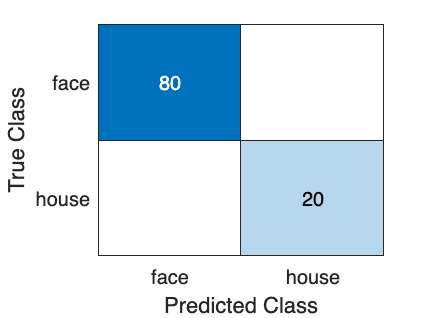

% Make a confusion matrix
trainconchart = confusionchart(y_train, yhat_train);

trainconchart_matrix = trainconchart.NormalizedValues;
accuracy = (trainconchart_matrix(1,1) + trainconchart_matrix(2,2)) / sum(sum(trainconchart_matrix))

accuracy = 1

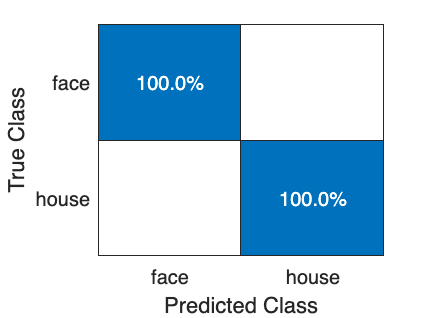


trainconchartNorm = confusionchart(y_train,yhat_train,'Normalization','row-normalized');

tpr_face = trainconchartNorm.NormalizedValues(1,1)

tpr_face = 1

tpr_house = trainconchartNorm.NormalizedValues(2,2)

tpr_house = 1

## Perform cross-validation to estimate how well your model performs

Note that you have to retrain the model on a subset of your training data and make predictions on the remaining training data (validation set). The number of parts you divide your data up into is the KFolds. 

% Perform cross-validation
KFolds = 5;
cvp = cvpartition(y_train, 'KFold', KFolds);
% Initialize the predictions to the proper sizes
validationPredictions = y_train;
numObservations = size(predictors, 1);
numClasses = length(classNames);
validationScores = NaN(numObservations, numClasses);
for fold = 1:KFolds
    % trainingPredictors = predictors(cvp.training(fold), :);
    % trainingResponse = response(cvp.training(fold), :);
    trainingPredictors = X_train(cvp.training(fold), :);
    trainingResponse = y_train(cvp.training(fold), :);

    % Apply a PCA to the predictor matrix.
    numericPredictors = double(trainingPredictors);
    % 'inf' values have to be treated as missing data for PCA.
    numericPredictors(isinf(numericPredictors)) = NaN;
    [pcaCoefficients, pcaScores, ~, ~, explained, pcaCenters] = pca(...
        numericPredictors, ...
        'NumComponents', numComponentsToKeep);
    trainingPredictors = array2table(pcaScores(:,:));

    % Train a classifier
    % This code specifies all the classifier options and trains the classifier.
    classificationSVM = fitcsvm(...
        trainingPredictors, ...
        trainingResponse, ...
        'KernelFunction', 'linear', ...
        'PolynomialOrder', [], ...
        'KernelScale', 'auto', ...
        'BoxConstraint', 1, ...
        'Standardize', true, ...
        'Cost', costMatrix, ...
        'ClassNames', classNames);


     % Create the result struct with predict function
    pcaTransformationFcn = @(x) [ (double(x) - pcaCenters) * pcaCoefficients ];
    svmPredictFcn = @(x) predict(classificationSVM, x);
    validationPredictFcn = @(x) svmPredictFcn(pcaTransformationFcn(x));

    % Compute validation predictions
    validationPredictors = X_train(cvp.test(fold), :);
    [foldPredictions, foldScores] = validationPredictFcn(validationPredictors);

    % Store predictions in the original order
    validationPredictions(cvp.test(fold), :) = foldPredictions;
    validationScores(cvp.test(fold), :) = foldScores;
end

### Exercise: Make a cross-valiation confusion matrix. Calcuate the cross-validation accuracy and true positive rates.

trainconchart_CV = confusionchart(y_train,yhat_train);

accuracy_test_CV = (trainconchart_CV.NormalizedValues(1,1) + trainconchart_CV.NormalizedValues(2,2)) / sum(sum(trainconchart_CV.NormalizedValues))

accuracy_test_CV = 1


trainconchartNorm_CV = confusionchart(y_train,yhat_train,'Normalization','row-normalized');

tpr_face_test_CV = trainconchartNorm_CV.NormalizedValues(1,1)

tpr_face_test_CV = 1

tpr_house_test_CV = trainconchartNorm_CV.NormalizedValues(2,2)

tpr_house_test_CV = 1

## Assess with test data

To test the how well your model (trained with skewed data) works on the balanced data, you can use this line of code:

testPredictions = trainedClassifier.predictFcn(X_test_skew);

#### Exercise: Use the classifier to predict results on the imbalanced test data (_skew). Make a confusion matrix. Calculate the test accuracy and true positive rates for the balanced data.

testconchart = confusionchart(y_train,yhat_train);

accuracy_test = (testconchart.NormalizedValues(1,1) + testconchart.NormalizedValues(2,2)) / sum(sum(testconchart.NormalizedValues))

accuracy_test = 1

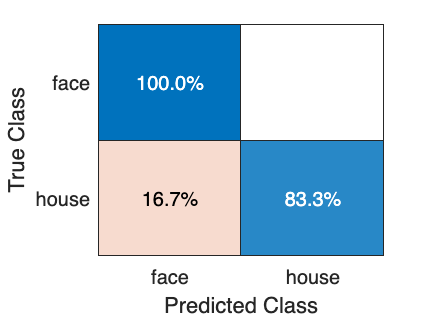


testconchartNorm = confusionchart(y_test_skew,testPredictions,'Normalization','row-normalized');

tpr_face_test = testconchartNorm.NormalizedValues(1,1)

tpr_face_test = 1

tpr_house_test = testconchartNorm.NormalizedValues(2,2)

tpr_house_test = 0.8333

#### Calculate the test accuracy and true positive rates for the balanced data.

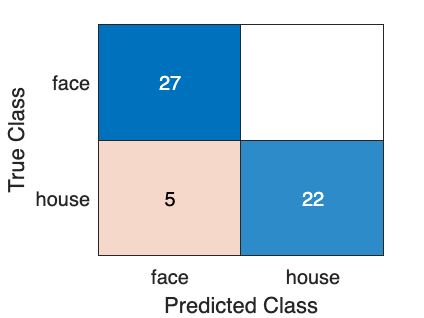

testPredictions_balanced = trainedClassifier.predictFcn(X_test_balanced);
testconchart_balanced = confusionchart(y_test_balanced,testPredictions_balanced);

accuracy_test_balanced = (testconchart_balanced.NormalizedValues(1,1) + testconchart_balanced.NormalizedValues(2,2)) / sum(sum(testconchart_balanced.NormalizedValues))

accuracy_test_balanced = 0.9074

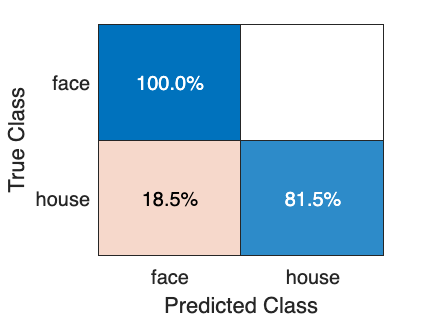


testconchartNorm_balanced = confusionchart(y_test_balanced,testPredictions_balanced,'Normalization','row-normalized');

tpr_face_test_balanced = testconchartNorm_balanced.NormalizedValues(1,1)

tpr_face_test_balanced = 1

tpr_house_test_balanced = testconchartNorm_balanced.NormalizedValues(2,2)

tpr_house_test_balanced = 0.8148